# In-class Test of Multiplicative Updates Implementation

Here we'll do a quick test of our in-class implementation of multiplicative updates for SymNMF!

First, we'll build a small synthetic dataset that we know should factorize very well via SymNMF!

n = 100;
k = 10;

H_actual = abs(randn(n,k));
A = H_actual*H_actual';

Next, we'll train a SymNMF model of rank 10 on this dataset and visualize the error at each iteration of our implementation of multiplicative updates.

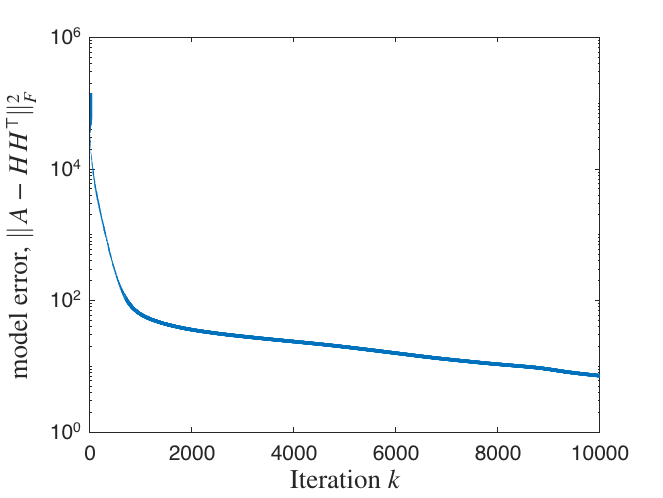

M = 10000;    %declare number of iterations
alpha = 1;
[newH,errs] = multUp_SymNMF(A,10,alpha,M);             %train the model

figure;
semilogy(0:M,errs,'LineWidth',3)                      %plot the error
set(gca,'Fontsize',14)
xlabel("Iteration $k$",'FontSize',18,'Interpreter','latex')
ylabel("model error, $\|A - HH^\top\|_F^2$",'FontSize',18,'Interpreter','latex')